g = 9.81;
R = 4.4;
m = 0.057;%kg masa kulki

a = 0.03005;
b = -242.5;
c = -1.422;
d = 0.1096;

z = 0 : 0.001: 0.03;
len = length(z);

punkty_row = zeros(3, len);
macierze_A = cell(len, 1);
macierze_B = cell(len, 1);

%punty_row(1,:) pozycje
%punty_row(2,:) prędkości
%punty_row(3,:) prądy

for i = 1:len
   [temp_p, temp_j, temp_b] = punkty(z(i));
   punkty_row(:,i) = temp_p;
   macierze_A{i} = temp_j;
   macierze_B{i} = temp_b;
end 
clear temp_b temp_j temp_p

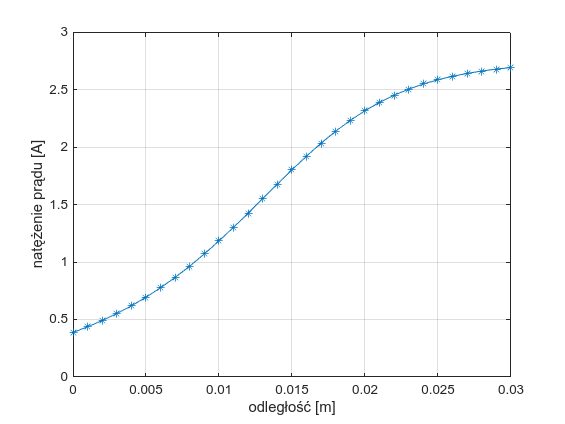

plot(punkty_row(1,:),punkty_row(3,:), Marker ="*");
grid on;
xlabel("odległość [m]")
ylabel('natężenie prądu [A]')

 p = polyfit(punkty_row(1,:),punkty_row(3,:), 7);

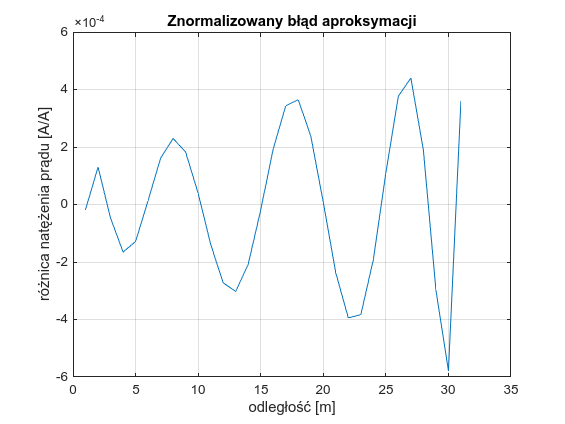

 py = polyval(p,punkty_row(1,:) );
 figure 
 plot((punkty_row(3,:)-py)/max(punkty_row(3,:)));
 grid on;
 title("Znormalizowany błąd aproksymacji")
 xlabel("odległość [m]")
 ylabel('różnica natężenia prądu [A/A]')

%sterowalość/iteracja działania/wyliczanie nastaw dla LQRI

wagi_pozycja = zeros(1,len);
wagi_predkosc = zeros(1,len);
wagi_natezenie = zeros(1,len);
wagi_calka = zeros(1,len);

for i = 1:len
    ster = [macierze_A{i} macierze_A{i}*macierze_B{i}];
    
    if rank(ster) < 3
    disp('oh noes for i = ')
    i
    end


    A = macierze_A{i};
    B = macierze_B{i};
        
    zero = [0;0;0];
    m_wec=[1 0 0 0];
    A_new = [A zero];
    A_new = [A_new; m_wec];
    B_new = [B; 0];

    ster = [macierze_A{i} macierze_A{i}*macierze_B{i}];
    
    if rank(ster) < 3
    disp('oh noes for i = ')
    i
    end

    waga_uchybu = 1/(0.0005)^2;
    K = lqr(A_new, B_new, diag([1/(0.005)^2,0,1/(0.07)^2, waga_uchybu]), 3000)/2;
    wagi_pozycja(i)= K(1);
    wagi_predkosc(i)= K(2);
    wagi_natezenie(i)= K(3);
    wagi_calka(i) = K(4);



end 

clear ster

l = 11;
z(l)

ans = 0.0100


A = macierze_A{l};
B =  macierze_B{l};
%budowa nowych macierzy A i B z dodatkowym stanem x4 - ca³k¹ pozycji
zero = [0;0;0];
m_wec=[1 0 0 0];
A_new = [A zero];
A_new = [A_new; m_wec];

B_new = [B; 0];

waga_uchybu = 1/(0.0005)^2; %Waga uchybu po³o¿enia
% waga_uchybu = 120000;

% K = lqr(linsys1.a, linsys1.b, diag([1/(0.005)^2,0,1/(0.07)^2]), 100)/4.2
% K = lqr(A_new, B_new, diag([1/(0.005)^2,0,1/(0.07)^2, 1/(0.007)^2]), 100)/4.2 % dzia³a po 250 sekundach xddd 
K = lqr(A_new, B_new, diag([1/(0.005)^2,0,1/(0.07)^2, waga_uchybu]), 3000)/2;

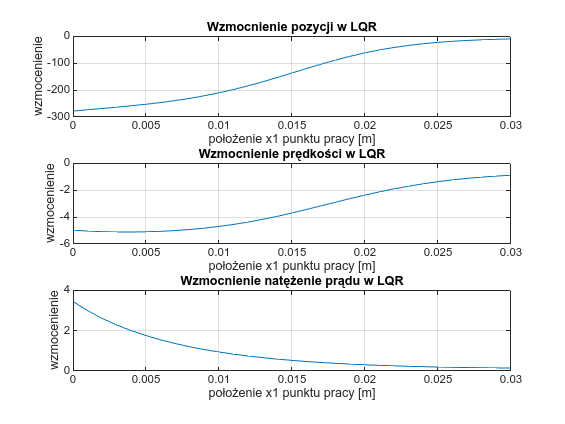

%plotowanie sterowań regulatora LQRI

figure 
subplot(3, 1, 1);
plot(z,wagi_pozycja);
title("Wzmocnienie pozycji w LQR")
xlabel("położenie x1 punktu pracy [m]")
grid on;
ylabel("wzmocenienie")

subplot(3, 1, 2);
plot(z,wagi_predkosc);
grid on;
title("Wzmocnienie prędkości w LQR")
xlabel("położenie x1 punktu pracy [m]")
ylabel("wzmocenienie")

subplot(3,1, 3);
plot(z, wagi_natezenie);
grid on;
title("Wzmocnienie natężenie prądu w LQR")
xlabel("położenie x1 punktu pracy [m]")
ylabel("wzmocenienie")

mwag_cal = mean(wagi_calka)

mwag_cal = -18.2574

%aproksymacja wzocnień a pomocą wielomianów, bo jest najszybciej

% global p_z p_i P_V
p_z = polyfit(z,wagi_pozycja, 7);



p_v = polyfit(z,wagi_predkosc, 7);

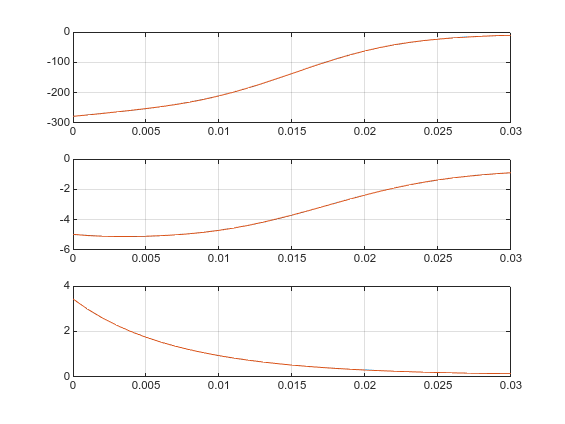



p_i = polyfit(z, wagi_natezenie, 6);

figure 
subplot(3, 1, 1);
plot(z,wagi_pozycja);
hold on;
plot(z, polyval(p_z,z))
grid on;

subplot(3, 1, 2);
plot(z,wagi_predkosc);
hold on;
plot(z, polyval(p_v,z))
grid on;

subplot(3,1, 3);
plot(z, wagi_natezenie);
hold on;
plot(z, polyval(p_i,z))
grid on;

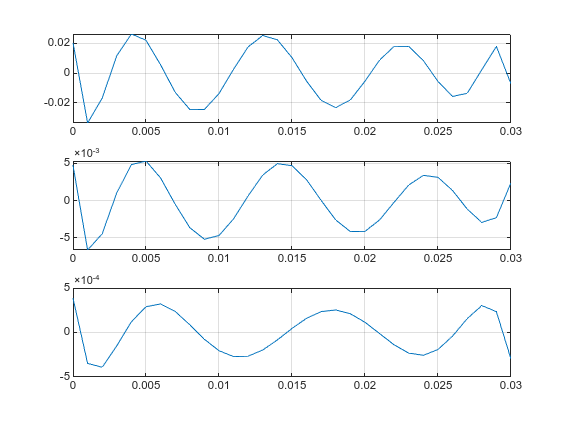



figure 
title("Błąd aproksymacji")
subplot(3, 1, 1);
plot(z,(wagi_pozycja - polyval(p_z,z))/max(wagi_pozycja));
grid on;


subplot(3, 1, 2);
plot(z,(wagi_predkosc - polyval(p_v,z))/max(wagi_predkosc));
grid on; 

subplot(3,1, 3);
plot(z, (wagi_natezenie - polyval(p_i,z))/max(wagi_natezenie));
grid on;